# Myosin-cortex interaction

%CLEAR THE WORKSPACE

clear all
clc

%ARRAYS OF PARAMETERS

str = ["cell 1 Bleb 1", "cell 1 Bleb 2", "cell 1 Bleb 3", "cell 1 Bleb 4"...
   "cell 2 Bleb A1", "cell 2 Bleb B1", "cell 2 Bleb C1", "cell 2 Bleb C2"...
  "cell 2 Bleb D1", "cell 2 Bleb D2", "cell 2 Bleb E1", "cell 3 Bleb B1"...
  "cell 3 Bleb B2", "cell 3 Bleb B3", "cell 3 Bleb B4", "cell 4 Bleb B1", ...
  "cell 4 Bleb B2", "cell 5 Bleb B1", "cell 6 Bleb B1", "cell 7 Bleb B1", "cell 8 Bleb B1", ...
  "cell 10 Bleb B1", "cell 10 Bleb B2", "cell 12 Bleb B1", "cell 15 Bleb B1", ...
  "cell 15 Bleb B2"];

data_sheet = ["cell001B1.xlsx", "cell001B2.xlsx", "cell001B3.xlsx","cell001B4.xlsx", ...
    "cell002BA1.xlsx", "cell002BB1.xlsx", "cell002BC1.xlsx", "cell002BC2.xlsx", ... 
    "cell002BD1.xlsx", "cell002BD2.xlsx", "cell002BE1.xlsx","cell003B1.xlsx", ...
   "cell003B2.xlsx", "cell003B3.xlsx", "cell003B4.xlsx", "cell004B1.xlsx", "cell004B2.xlsx", ...
   "cell005B1.xlsx", "cell006B1.xlsx", "cell007B1.xlsx", "cell008B1.xlsx", "cell0010AB1.xlsx",...
   "cell0010BB2.xlsx", "cell0012B1.xlsx", "cell0015AB1.xlsx", "cell0015AB2.xlsx" ];

frames = [15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15, 15 ,15 ,15, 14 ...
    14, 14, 14, 14, 14, 14, 14];

bleb_start = [2, 3, 4, 12, 9, 3, 3, 2, 8, 7, 11, 4, 5, 6, 9, 10, 11, 4, 6, 6, 6, 10, 8, 7, 12];

bleb_frame1 = [18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 18, 17 ...
    17, 17, 17, 17, 17, 17, 17];

bleb_frame2 = [35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35, 35 ,35 ,35, 33 ...
    33, 33, 33, 33, 33, 33, 33];


% ALLOCATE SPACE

counter = zeros(1,max(frames)-min(bleb_start));

mean = zeros(1,max(frames)-min(bleb_start));

solutions = zeros(3*length(bleb_start), max(frames));

temp = zeros(length(bleb_start), max(frames));

stderror = zeros(1,max(frames)-min(bleb_start));

% MAIN LOOP TO RUN MAX FXN AND SAVE RESULTS IN SOLUTION VECTOR

for i = 0:length(bleb_start)-1
    
    [solutions(3*i+1,:), solutions(3*i+2,:), solutions(3*i+3,:)] = max_fxn(str(i+1), data_sheet(i+1), bleb_start(i+1), frames(i+1), 0, bleb_frame1(i+1), bleb_frame2(i+1));
      
end


% Loop to start all the columns where the first bleb starts

for i=0:length(bleb_start)-1
    
    temp(3*i+1:3*i+3,1:max(frames)-bleb_start(i+1)+1) = solutions(3*i+1:3*i+3,bleb_start(i+1):end);
    
    
end

solutions = temp

solutions =     1.5716    1.7545    1.5821    1.2264    1.3946    1.6378    1.2689    1.8242    2.0869    1.8245    2.1991    2.1655    1.7117    1.5457         0
    2.8039    3.0600    2.5101    2.9652    2.5353    2.8865    3.1179    2.9316    3.3006    2.8069    2.8953    2.0687    2.5351    1.9037         0
    4.0649    4.1011    3.0396    3.9207    3.7831    3.9213    4.6309    5.1365    4.2221    3.8134    4.2815    3.4659    3.7096    4.0869         0
    1.7080    2.2358    2.6063    2.6965    2.6850    2.3298    2.1595    2.2785    2.2379    2.2039    2.3694    1.6940    2.1303         0         0
    3.1474    2.7389    2.2063    2.1675    1.8012    1.4999    1.1765    1.5260    1.5945    1.7467    1.9368    2.3145    1.6723         0         0
    3.4686    3.2450    3.5228    2.7712    3.1663    3.6998    3.5629    3.6004    2.6766    2.6516    2.4369    2.5305    2.4887         0         0
    3.9208    4.6703    5.0491    3.8882    3.6577    4.1597    4.3519    4.3479  

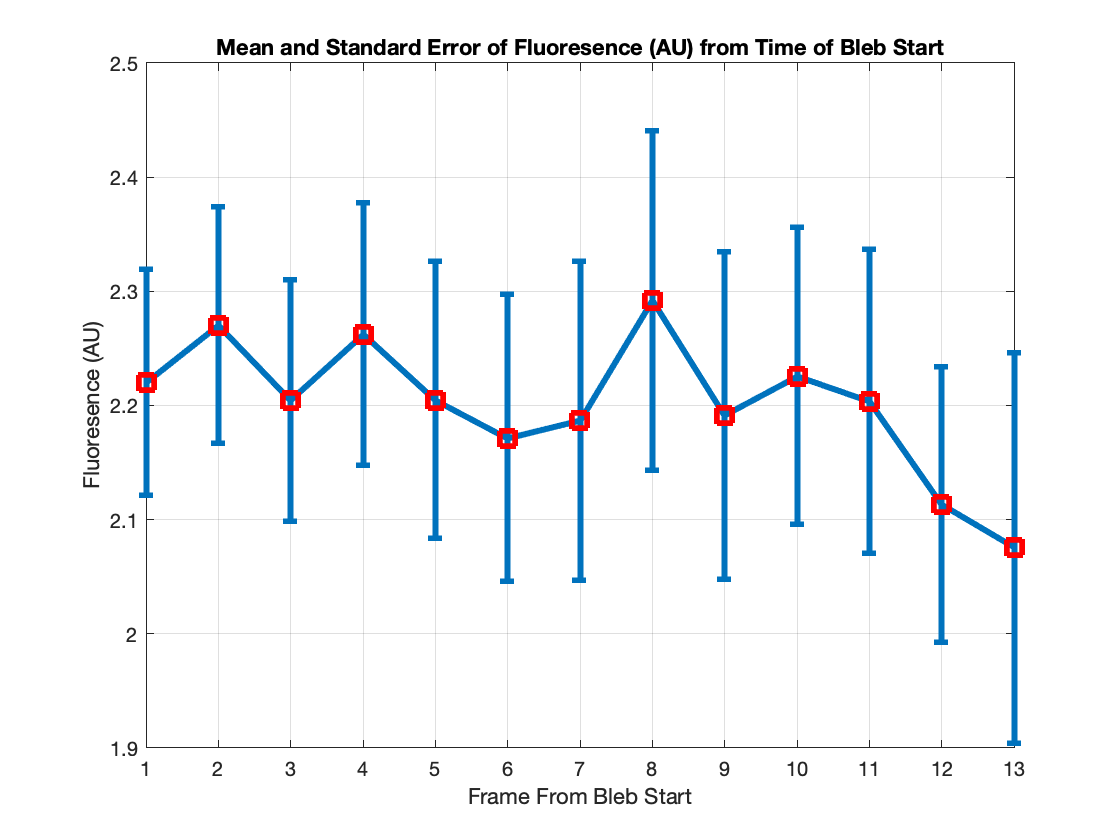



% CALCULATING STANDARD DEVIATION OF EACH COLUMN

temp = solutions; %set a temp matrix equal to solutions matrix
temp(temp==0)=NaN; %change all zeros in the matrix to NaN
std_columns = nanstd(temp,[],1); %take the standard deviation of the columns ignoring all NaN entries
std_columns = std_columns(1:max(frames)-min(bleb_start)); %extract all but the NaN columns from matrix

% LOOP TO DETERMINE HOW MANY NON-ZERO ENTRIES IN EACH COLUMN

for i = 1:max(frames)-min(bleb_start)
    
    counter(i) = sum(solutions(:,i)~=0);
    
end

% CALCULATE THE SUM OF EACH COLUMN 

sum_column_elements = sum(solutions);


% LOOP TO CALCULATE THE AVERAGE OF EACH COLUMN

for i = 1:max(frames)-min(bleb_start)
    
    mean(i) = sum_column_elements(i)/counter(i);
    
end

% LOOP TO CALCULATE THE STANDARD ERROR

for i = 1:max(frames)-min(bleb_start)
    
    stderror(i) = std_columns(i)/sqrt(counter(i));
    
end


% PLOT THE MEAN AND STANDARD DEVIATION

errorbar(mean, stderror,'-s','MarkerSize',10,...
    'MarkerEdgeColor','red',"LineWidth",3)
grid on
xticks(0:1:max(frames)-min(bleb_start))
xlim([1 max(frames)-min(bleb_start)])
xlabel('Frame From Bleb Start')
ylabel('Fluoresence (AU)')
title('Mean and Standard Error of Fluoresence (AU) from Time of Bleb Start')